# read_sin_00.m

View parameters, plot waveform, compute and display spectrum. Verify that the frequency of the sinusoid (as measured using the FFT) is the expected frequency. 

clear

## Load .wav file

[x, Fs] = audioread('sin_00_mono.wav');
[nbits, opts] = audioread('sin_00_mono.wav');

whos

  Name          Size            Bytes  Class     Attributes

  Fs            1x1                 8  double              
  nbits      8000x1             64000  double              
  opts          1x1                 8  double              
  x          8000x1             64000  double              



Fs

Fs = 8000

nbits

nbits =    -1.0000
   -1.0000
   -0.9922
   -0.8281
   -0.2891
   -0.6641
   -0.1719
   -0.5078
    0.1719
   -0.3672


opts

opts = 8000

soundsc(x, Fs)

## Plot waveform

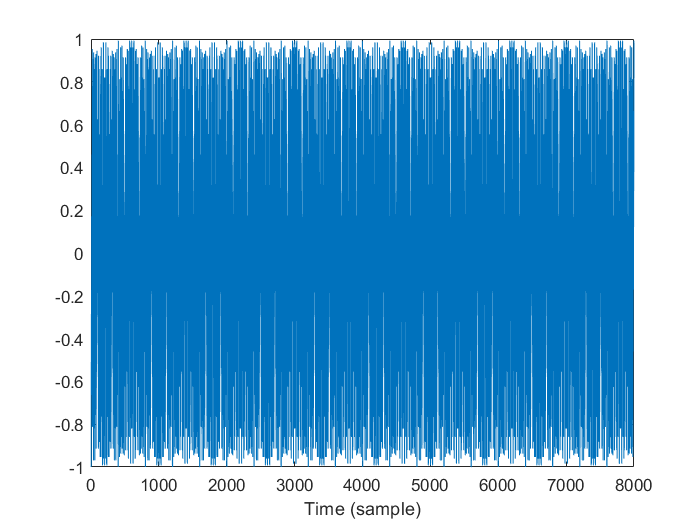

figure(1)
clf
plot(x)
xlabel('Time (sample)')

## Time axis in seconds

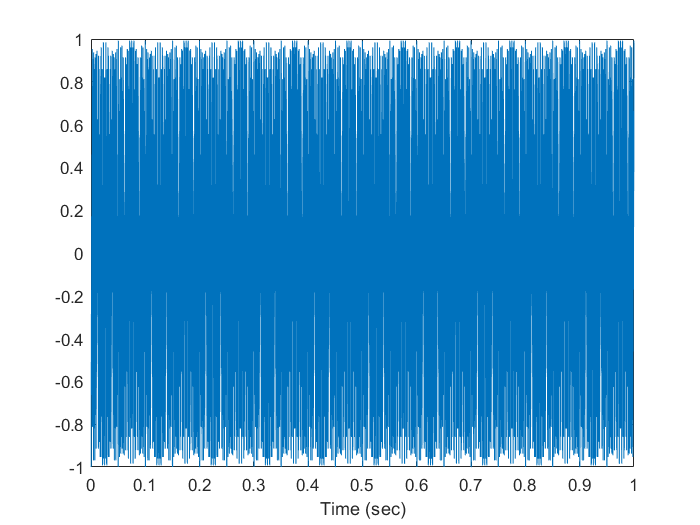

N = length(x);
t = (1:N)/Fs;

figure(1)
clf
plot(t, x)
xlabel('Time (sec)')

## Zoom in to 50 msec

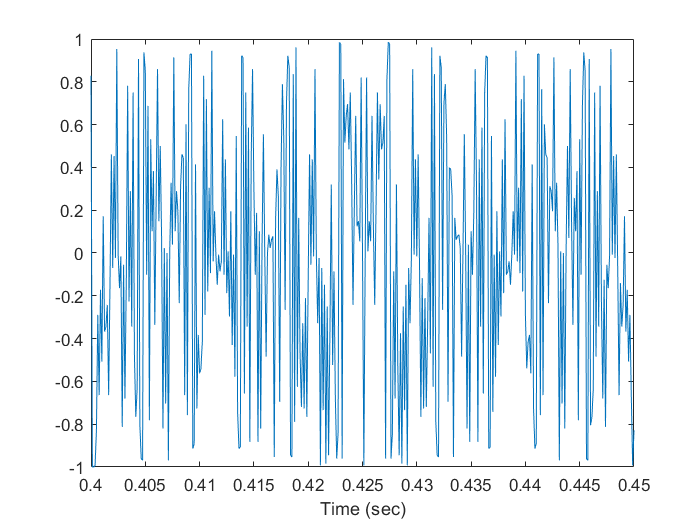

xlim(0.4 + [0 0.050])

## What is the quantization increment ?

x(100:110)

ans =    -0.1875
    0.0078
   -0.2969
    0.1953
   -0.4297
   -0.0078
   -0.5781
    0.5469
   -0.7422
   -0.9141


x(100:110) * 2^14

ans =        -3072
         128
       -4864
        3200
       -7040
        -128
       -9472
        8960
      -12160
      -14976


x(100:110) * 2^15

ans =        -6144
         256
       -9728
        6400
      -14080
        -256
      -18944
       17920
      -24320
      -29952


% Quantization size is 1 / 2^15
2^15

ans = 32768

## Frequency spectrum

Use Fast Fourier Transform (FFT)

% Use power of 2 for FFT efficiency
N = length(x)

N = 8000

Nfft = 2^ceil(2+log2(N))        % Use FFT length longer than signal length

Nfft = 32768

## Compute Fourier transform

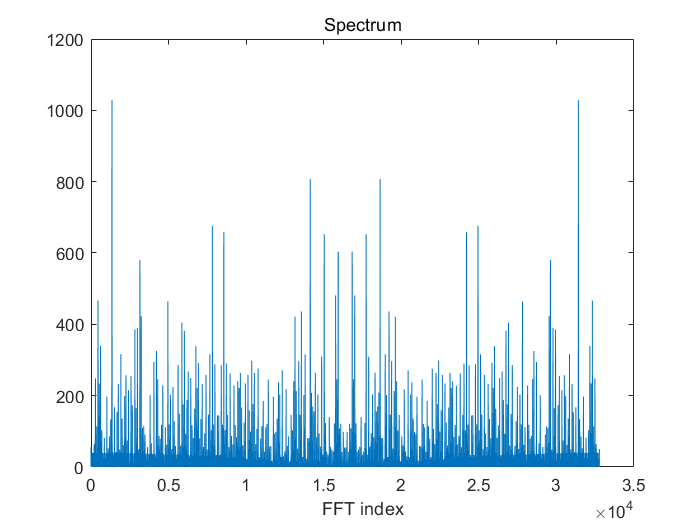

X = fft(x, Nfft);   
k = 0:Nfft-1;      % FFT index

figure(1)
clf
plot(k, abs(X))
xlabel('FFT index')
title('Spectrum')

## Center dc

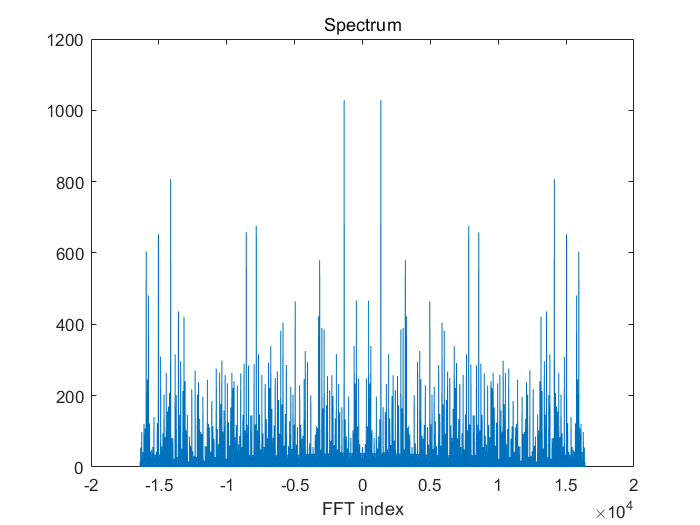

X2 = fftshift(X);
k2 = -Nfft/2 : Nfft/2-1;

figure(1)
clf
plot(k2, abs(X2))
xlabel('FFT index')
title('Spectrum')

## Normalized frequency

Normalized frequency is in units of [cycles per sample]

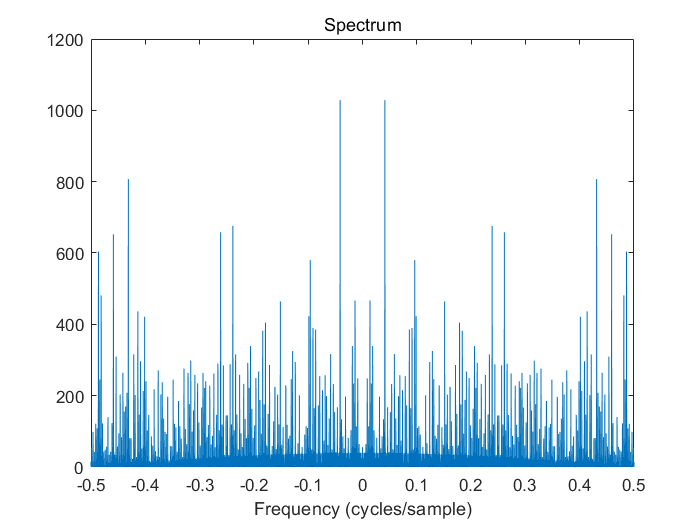

fn = ( -Nfft/2 : Nfft/2-1 ) / Nfft;

figure(1)
clf
plot(fn, abs(X2))
xlabel('Frequency (cycles/sample)')
title('Spectrum')

## Frequency in Hz

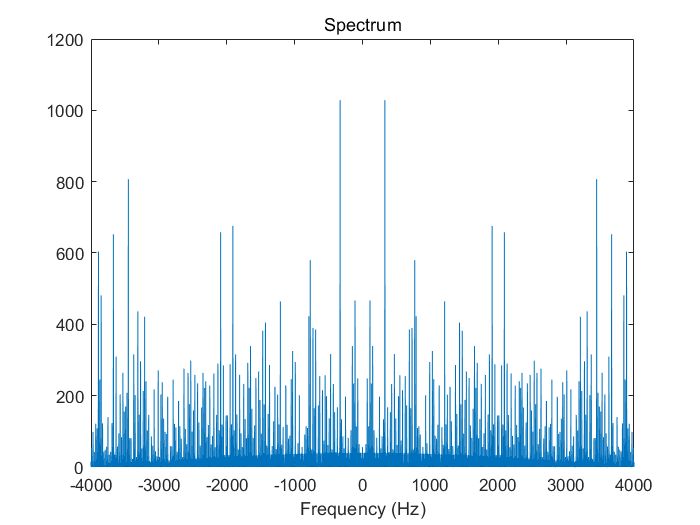

f = fn * Fs;

figure(1)
clf
plot(f, abs(X2))
xlabel('Frequency (Hz)')
title('Spectrum')

Zoom to frequency band [200 350] Hz. Notice the sidelobes

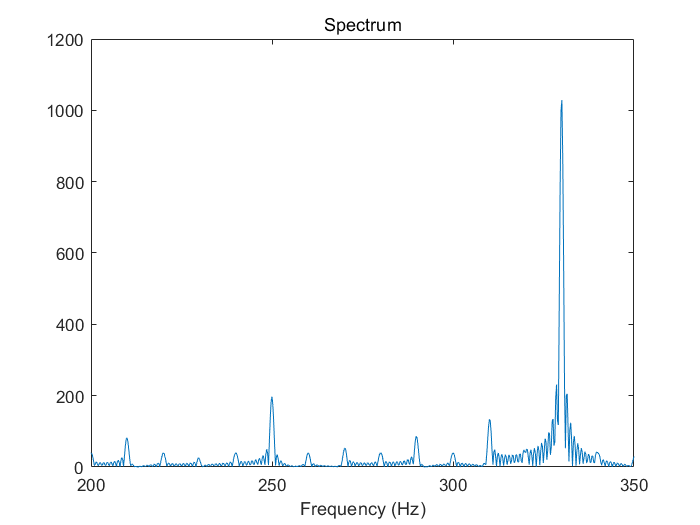

xlim([200 350])

## Fourier transform in dB

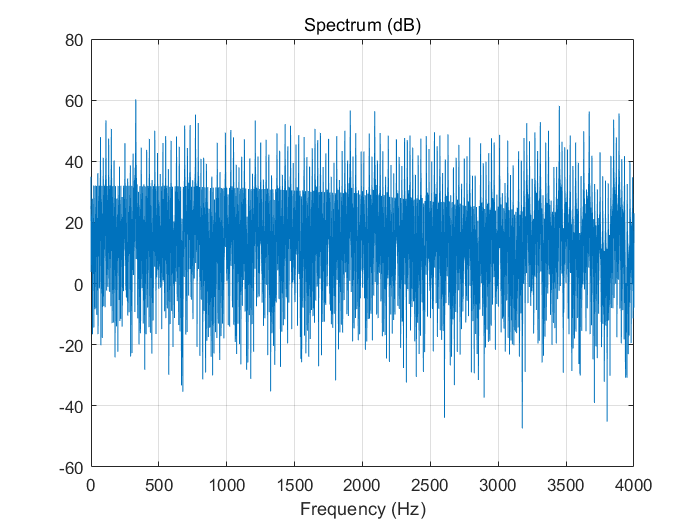

X_dB = 20*log10(abs(X2));

figure(1)
clf
plot(f, X_dB)
xlabel('Frequency (Hz)')
title('Spectrum (dB)')

xlim([0 Fs/2])
grid

print -dpdf read_sin_00_spectrum